# **Interpolação**

**Exercício 1:** Encontre o polinômio de grau <= 2 que interpola os pontos (-1,4),(0,1), (2,-1).

Implementação do sistema a ser resolvido:

%Encontra o polinômio interpolador por resolução do sistema 

x = [-1; 0; 2]; %Vetor de dados tabelados x;
y = [4;1;-1]; %Vetor de dados tabelados de f(x);

%1 -  Criação da matriz de Vandermonde A
n = length(x); %número de pontos
k = 2;  %grau do polinômio

for i = 1:n
    for j = 1:k+1
        A(i,j) = x(i)^(j);
    end    
end    
A

A =     -1     1    -1
     0     0     0
     2     4     8


%Resolução do sistema A*a = y, a = [a0, a1, a2]
a = A\y;

% p2 = a(1)+a(2)*(-0.5)+a(3)*(0.5).^2 %polinômio interpolador de grau <= 2

p2 = NaN

Graficamente,

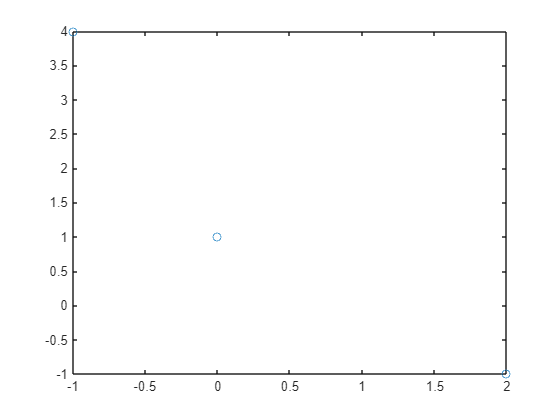

x1 = linspace(-1,2);%criação de um vetor de pontos linearmente espaçados num intervalo de [-1,2]
p2 = a(1)+a(2)*x1+a(3)*x1.^2;%polinômio interpolador
figure
plot(x,y,'o')
hold on
plot(x1,p2)
hold off

Função POLYFIT:

%Utilizar a função do MatLab polyfit p = [a2,a1,a0] e polyval(p,x0)
p = polyfit(x,y,2) %enconta os coeficientes

p =     0.6667   -2.3333    1.0000


p0 = polyval(p,0) % avalia o polinômio interpolado no ponto desejado

p0 = 1

**Polinômio de Lagrange**


$$p_{n}(x) = \displaystyle \sum_{k=0}^{n} y_{k}L_{k}(x)$$



$$L_{k}(x) = \displaystyle \frac{\prod_{j=0,j\neq k}^{n} (x-x_{j})}{ \prod_{j=0,j\neq k}^{n}(x_{k}-x_{j})}$$


Implementação da forma de Lagrange:

x0 = [-1;0;2];
y = [4;1;-1];

syms x
n = length(x);
s = 0;

% algoritmo lagrange
for k = 1:n
    prod1 = 1;
    prod2 = 1;
    for j = 1:n
        if(j ~= k)
            prod1 = prod1 * (x-x0(j));
            prod2 = prod2 * (x0(k) - x0(j));
        end
    end
    L(k) = prod1/prod2;
    s = s + L(k)*y(k);
end
s

$$s = \frac{4\,x\,\left(x-2\right)}{3}-\frac{x\,\left(x+1\right)}{6}-\frac{\left(x+1\right)\,\left(x-2\right)}{2}$$

% L0 = ((x-x0(2))*(x-x0(3)))/((x0(1)-x0(2))*(x0(1)-x0(3)))
% L1 = ((x-x0(1))*(x-x0(3)))/((x0(2)-x0(1))*(x0(2)-x0(3)))
% L2 = ((x-x0(1))*(x-x0(2)))/((x0(3)-x0(1))*(x0(3)-x0(2)))

%Encontra o polinômio interpolador usando a forma de Lagrange

**Exercício 2: **Os dados a seguir definem a concentração no nível do mar do oxigênio dissolvido em água fresca como função da temperatura 

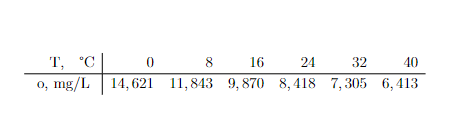

Obtenha estimativas de $o(27)$ usando 

a) Interpolação linear

%x0 = 24 e x1 = 32  pois 27°C pertence a esse intervalo
x = [24 32];
y = [8.418 7.305];

p = polyfit(x,y,1) %acha os coeficientes
polyval(p, 27)

b) Polinômio interpolador de Lagrange de grau $n\leq 5$.

clear
syms x
x0 = [0 8 16 24 32 40];
y = [14.621 11.843 9.870 8.418 7.305 6.413];

p =    -0.1391   11.7570


ans = 8.0006


n = length(x0);
s = 0;
prod = 1;

% algoritmo lagrange
for k = 1:n
    prod1 = 1;
    prod2 = 1;
    for j = 1:n
        if(j ~= k)
            prod1 = prod1 * (x-x0(j));
            prod2 = prod2 * (x0(k) - x0(j));
        end
    end
    L(k) = prod1/prod2;
    s = s + L(k)*y(k);
end

%para validar o resultado com o polyval, substituir o x por 27, deve dar o valor de 7.9682
o_27 = s; %da forma que está, ele retorna a equação
p = polyfit(x0,y,5);
o27 = polyval(p,27)

**Exercício 3: **Gere oito pontos igualmente espaçados para a função $f(t)=\sin^{2}{t}$ de $t=0$ a $2\pi$. Ajuste esses dado a com um polinômio interpolador de ordem 7.

clear
a = 0; %ponto inicial
b = 2*pi; %ponto final

o27 = 7.9682

h = (b-a)/7; %gera os pontos espaçados igualmente

x = a:h:b;
y = (sin(x)).^2;
p = polyfit(x,y,7)
syms t
p8(t) = p(1)*t^7 +p(2)*t^6 + p(3)*t^5 + p(4)*t^4 +p(6)*t^3 + p(7)*t^2 +p(8)*t
%Vetor de pontos igualmente espaçados
%[a,b] = [0,2*pi]
% h = (b-a)/7; 

**Exercício 4: **Com base no exercício 3, qual o erro cometido ao fazer ao utilizar um polinômio interpolador de ordem 7 para encontrar $f(5)$.

% Exercício 4: Cálculo do erro em t = 5

p =    -0.0000    0.0121   -0.2281    1.5866   -4.9290    6.3869   -2.0870    0.0000


clear
a = 0;

$$p8(t) = -\frac{1689604928674521\,t^{7}}{2535301200456458802993406410752}+\frac{6975968918934333\,t^{6}}{576460752303423488}-\frac{8218369765267803\,t^{5}}{36028797018963968}+\frac{893175056037827\,t^{4}}{562949953421312}+\frac{1797747292385547\,t^{3}}{281474976710656}-\frac{4699510437790137\,t^{2}}{2251799813685248}+\frac{6906119035216445\,t}{19807040628566084398385987584}$$

b = 2*pi;
h = (b - a)/7;
x = a:h:b;
y = (sin(x)).^2;
p = polyfit(x, y, 7); % Coeficientes do polinômio interpolador de ordem 7

t_alvo = 5;
aproximacao = polyval(p, t_alvo); % Avalia o polinômio em t = 5
valor_exato = (sin(t_alvo))^2; % Calcula o valor exato de f(5)
erro_absoluto = abs(valor_exato - aproximacao); % Calcula o erro absoluto

fprintf('O erro absoluto cometido em t = 5 é: %e\n', erro_absoluto);

O erro absoluto cometido em t = 5 é: 6.658253e-02


Solução: Como f(x) é conhecida, precisamos encontra a derivada de ordem oito e utilizar o Corolário 2:


$$|E_{7}(x) | \leq \frac{h^{8} * max|f^{(8)}(x)|}{4*8}$$
